# ETSMP Q4 eksamen – 2016

## Opgave 1: Stokastiske Variable 

En kontinuert stokastisk variabel X har følgende fordelingsfunktion (cdf): 

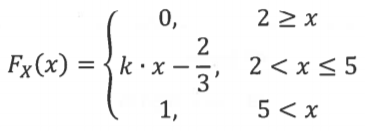

1) Vis at tæthedssfunktionen (pdf) er givet ved: 

CDF og PDF indeholder samme information og kan omregnes ved at differentiere:

syms x k
Fx(x) = piecewise(2 >= x, 0, 2 < x <= 5, k * x -2/3, 5 < x, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq 2\\ k\,x-\frac{2}{3} & \text{ if }x\in \left(2,5\right]\\ 1 & \text{ if }5<x \end{array}\right.$$

fx(x) = diff(Fx(x))

$$fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<2\\ k & \text{ if }x\in \left(2,5\right)\\ 0 & \text{ if }5<x \end{array}\right.$$

2) For hvilken værdi af k er $F_X \left(x\right)$ en gyldig tæthedsfunktion? Begrund svaret. 

For en gyldig tæthedsfunktion $F_X \left(x\right)<1$ skal k være:

k = solve(Fx(5) == 1, k)

3) Skitser tæthedsfunktionen og angiv navnet på fordelingsfunktionen.

k = 1/3;

$$k = \frac{1}{3}$$

Fx(x) = piecewise(2 >= x, 0, 2 < x <= 5, k * x -2/3, 5 < x, 1);
fx(x) = diff(Fx(x));
figure(1)
fplot(fx(x), [0, 7], 'linewidth',2);
title('Tæthedsfunktion');
xlabel('x');
ylabel('y');

Fordelingsfunktionen er uniform fordelt.

4) Brug $F_X \left(x\right)$ til at beregne sandsynligheden $\mathrm{Pr}\left(x\ge 3\right)$. Antag at $k=\frac{1}{3}$.

PrX = 1-Fx(3)

5) Bestem forventingsværdien og variansen af X udfra $f_X \left(x\right)$. Angiv desuden hvilken formler, der bruges til at bestemme værdierne. 

Antag at $k=\frac{1}{3}$.

Forventningsværdien findes ved:

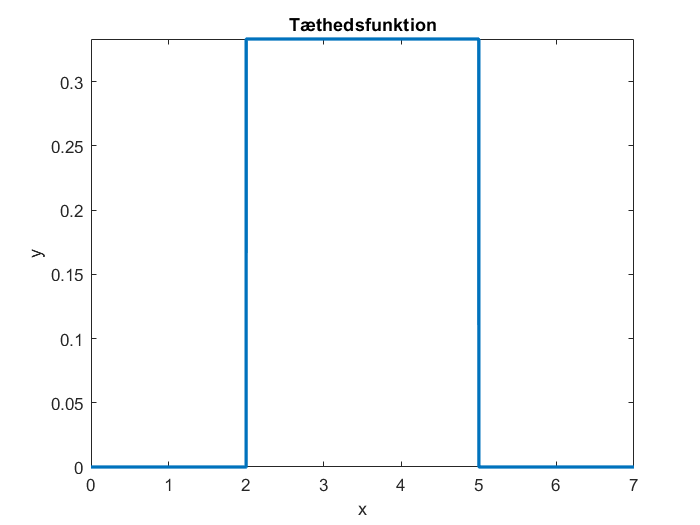

EX = int(x * fx(x),'x',-Inf,Inf)

Variansen findes ved:

varX = int(x^2*fx(x),'x',-Inf,Inf)-(EX^2)

$$PrX = \frac{2}{3}$$

## Opgave 2: Stokastiske Processer

format

$$EX = \frac{7}{2}$$

En kontinuert stokastisk process er givet ved:


$$X\left(t\right)=w+4$$


Hvor $w$ er normalfordelt efter $w~N\left(5,1\right)$.

1) Skitser fem realisationer af processen $X\left(t\right)$ mellem $t\in \left\lbrack 0;7\right\rbrack$.

Brug en Gauss-generator, det kan evt. være matlabs indbyggede generator, randn().

Angiv desuden hvordan de fem realisationer er fremkommet.

N = 5;

$$varX = \frac{3}{4}$$

t = [0:7];
mu = 5; variance = 1; sigma = sqrt(variance);
w = normrnd(mu, sigma, [1 N+1])
figure(2)
for i=1:N
    Xn = w(i)+4;
    plot(t, ones(1,length(t))*Xn);
    hold on
end
grid on
ylim([4 12])
xlabel("t"); ylabel("X(t)"); title("Realisationer af process");

2) Bestem ensemble middelværdien og ensemble variansen for processen $X\left(t\right)$.

Da $X\left(t\right)$ er givet ved:

Kan ensemble middelværdien findes ved:

uX = mu + 4

w =     3.9311    4.1905    2.0557    6.4384    5.3252    4.2451


Og ensemble variansen findes ved:

Hvor variansen af en konstant findes til at være lig med 0.

sigmaX = sigma + ((4^2)-(4^2))

3) Udvælg en af de fem realisationer og bestem middelværdien og variansen for denne realisation.

mean_w = mean(w(2)) + 4
var_w = var(w(1)) + ((4^2)-(4^2))

Angiv om processen $X\left(t\right)$ er WSS (stationær i den brede forstand) og om den er ergodisk. Begrund dine svar.

Da processen er uafhængig af tiden, og at middelværdien og variansen ikke ændrer sig, kan vi konstanter at processen 

er stationær i den brede forstand.

Processen er ikke ergodisk, da en realisation ikke siger noget om middelværdien, og variansen af hele processen. 

## Opgave 3: Sandsynlighedsregning

format

Hændelse A er, at en gravid fødte en pige i 2012. 

Hændelse B er, at hun fødte en dreng. 

Hændelse C er, at hun fødte et barn, der vejer over 4000g. 

20,2% af alle nyfødte drenge vejede i 2012 over 4000g. 12,8% afnyfødte piger vejede i 2012 over 4000g. 

`Prior: Sandsynlighed for at en gravid fødte en pige`

`Prior: Sandsynlighed for at en gravid fødte en dreng`

`Prior: Sandsynlighed for at en gravid fødte et barn der vejede over 4000g`

1) Hvis der blev født 29.785 drenge og 28.131 piger i 2012, hvad er sandsynligheden for hændelse A? 

`Antal af Hændelse A:`

`Antal af Hændelse B:`

`Samlet antal af Hændelse A+B:`

`Likelihood: Sandsynlighed for at en gravid fødte en pige givet fødselstal (Relative Frequency Approach)`

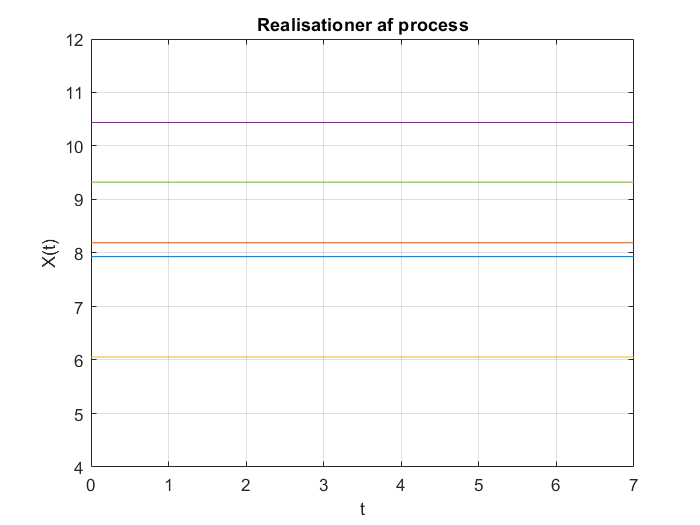

boys = 29785; girls = 28131;


PrA = girls/(boys+girls)

2) Hvad er den totale sandsynlighed for hændelse C?

`Likelihood: Sandsynlighed for at en gravid fødte en dreng`

PrB = 1-PrA

uX = 9

`Total Probality: Sandsynligheden for at en gravid fødte et barn over 4000g (Sum Rule)`

PrCA = 0.128; PrCB = 0.202;

sigmaX = 1


PrC = PrCA * PrA + PrCB * PrB

mean_w = 8.1905

3) Hvad var sandsynligheden for at den fødende fik en pige, hvis det oplyses, at hendes barn vejede over 4000g ved fødslen?

`Posterior: Sandsynligheden for at en gravid fødte en pige givet at barnet vejede over 4000g (Bayes Rule)`

PrAC = (PrCA * PrA) / PrC

var_w = 0

## Opgave 4: Statistik

Vi måler højden på studerende i en klasse, der består af 19 kvinder og 35 mænd. Højderne antages at være normalfordelt. 

Middelværdien for kvinder i klassen er $\hat{\mu_1 =1\ldotp 68}$m, med en estimeret varians på $s_1^2 =0\ldotp 10$. 

Middelværdien for mænd i klassen er $\hat{\mu_2 } =1\ldotp 78$m med en estimeret varians på $s_2^2 =0\ldotp 20$

1) Opstil et hypotese test, for at bestemme om middelværdien af mænd og kvinder i klassen er den samme. 

Null hypotese


$$H_0 =\mu 1=\mu 2$$


Alternative hypotese


$$H_1 =\mu 1\not= \mu 2$$


2) Angiv hvilken statistisk test du vil udføre for at teste hypotesen. Begrund dit svar.

Da variansen er ukendt, og dataen er normalt fordelt, så bruges der en t-test på forskellen af middelværdierne.

3) Estimér forskellen i middelværdierne $\delta$ og standard afvigelsen $\sigma$ for forskellen.

Middelværdien kan estimeres ved:

mu1 = 1.68; n1 = 19; mu2 = 1.78; n2  = 35; s1 = 0.1; s2 = 0.2;
average = abs(mu1-mu2)

Variansen estimeres ved:

Og standard afvigelsen findes:

std = sqrt((1/(n1+n2-2))*((n1-1)*s1+(n2-1)*s2))

4) Anvend en t-test til hypotese test af din hypotese. Kan NULL hypotesen afvises med et signifikansniveau på 0,05? 

Begrund dit svar. 

t = average/(std*sqrt((1/n1)+(1/n2)))

average = 0.1000

P værdien kan udregnes ved at anvende funktionen for student t cumulative distribution:

pval = 2*(1-tcdf(abs(t),(n1+n2)-2))

std = 0.4067

Vi kan ikke afvise null hypotesen da $p>0\ldotp 05$.

5) Opstil og find 95% konfidens intervallet for $\delta$. Angiv hvilkenn formel, der er brugt.

% Inivers student t fordeling
t0 = tinv(0.975,(n1+n2-2))

t = 0.8629

lower_bound = average-t0*std*sqrt((1/n1)+(1/n2))
upper_bound = average+t0*std*sqrt((1/n1)+(1/n2))

pval = 0.3921

t0 = 2.0066

lower_bound = -0.1325

upper_bound = 0.3325